## Cinematic Control

### Cubic Splin

Expression: q(t) = a + b * [ t - ti ] + c * [ t - ti ]^2 + d * [ t - ti ]^3

where:

- a = qi

- b = qi_dot

- c = 3/(T^2) * [ q(i+1)_dot - qi_dot ] - 1/T * [ q(i+1)_dot + 2*qi_dot ]

- d = -2/(T^3) * [ q(i+1)_dot - qi_dot ] - 1/(T^2) * [ q(i+1)_dot + qi_dot ]

- T = t(i+1) - ti

Two ways to calculate step velocity qi_dot:

First way:

- qi_dot = 0     if sgn(qi - q(i-1)) != sgn(q(i+1) - qi)

- qi_dot = 1/2 * [ [q(i+1) - qi]/[t(i+1) - ti] + [qi - q(i-1)]/[ti - t(i-1)] ]     if sgn(qi - q(i-1)) == sgn(q(i+1) - qi)    or   q(i-1) == qi   or   qi == q(i+1)

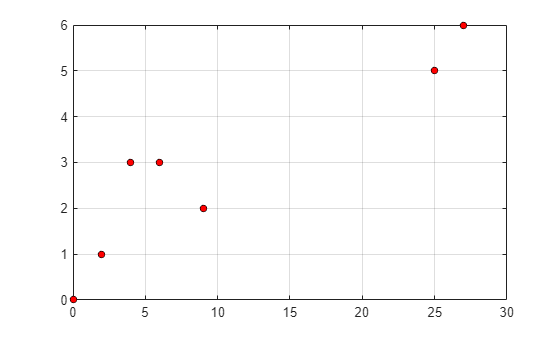

t = [0 2 4 6 9 25 27];
q = [0 1 3 3 2 5 6];
n = length(q);
dt = 0.1;

% Ploting point to reach
figure;
plot(t,q, 'o', 'MarkerSize', 5, 'MarkerFaceColor', 'r', 'MarkerEdgeColor','k');
grid on;
xticks(0:5:30); yticks(0:6); xlim([0 30]); ylim([0 6]);

% Calculating for step velocities
qd = [0 0];              % [q1_dot qk_dot]
for i = 2:n-1
    if sign(q(i)-q(i-1)) == sign(q(i+1)-q(i)) || q(i-1) == q(i) || q(i) == q(i+1)
        q_dot = 1/2 * ((q(i+1) - q(i))/(t(i+1) - t(i)) + (q(i) - q(i-1))/(t(i) - t(i-1)));
        qd = [qd(1:end-1) q_dot qd(end)];
    elseif sign(q(i)-q(i-1)) ~= sign(q(i+1)-q(i))
        qd = [qd(1:end-1) 0 qd(end)];
    end
end
qd

qd =          0    0.7500    0.5000   -0.1667         0    0.3438         0


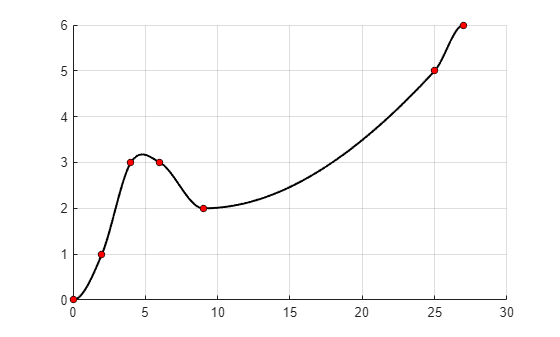

% Calculating trayectory
qt = []; q_dot = []; q_ddot = []; tt = [];
for i = 2:n
    a = q(i-1);
    b = qd(i-1);
    T = t(i) - t(i-1);
    c = 3/(T^2) * (q(i) - q(i-1)) - 1/T * (qd(i) + 2*qd(i-1));
    d = -2/(T^3) * (q(i) - q(i-1)) + 1/(T^2) * (qd(i) + qd(i-1));
    
    if i == 2
        ti = t(i-1):dt:t(i);
    else
        ti = (t(i-1)+dt):dt:t(i);
    end
    tau = ti - t(i-1);

    qi = a + b*tau + c*tau.^2 + d*tau.^3;
    qv = b + 2*c * tau + 3*d * tau.^2;
    qa = 2*c + 6*d * tau;
    
    qt = [qt qi];
    q_dot = [q_dot qv];
    q_ddot = [q_ddot qa];
    tt = [tt ti];
end

% Ploting trayectory
figure;
hold on; grid on;
plot(tt, qt, 'k', 'LineWidth', 1.5);
plot(t, q, 'o', 'MarkerSize', 5, 'MarkerFaceColor', 'r', 'MarkerEdgeColor','k');
xticks(0:5:30); yticks(0:6); xlim([0 30]); ylim([0 6]);
hold off;

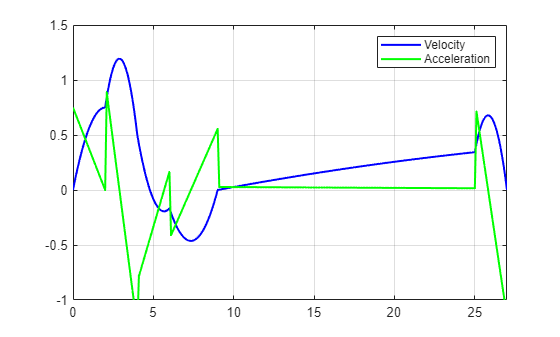

% Ploting step velocities and accelerations
figure;
plot(tt, q_dot, 'b', tt, q_ddot, 'g', 'LineWidth', 1.5);
xticks(0:5:30); yticks(-1:0.5:1.5); xlim([0 27]); ylim([-1 1.5]);
legend('Velocity', 'Acceleration');
grid on;

% Acceleration line not quite accurate :(
% It appears one unit traslated vertically in the graph of the book

Second way:

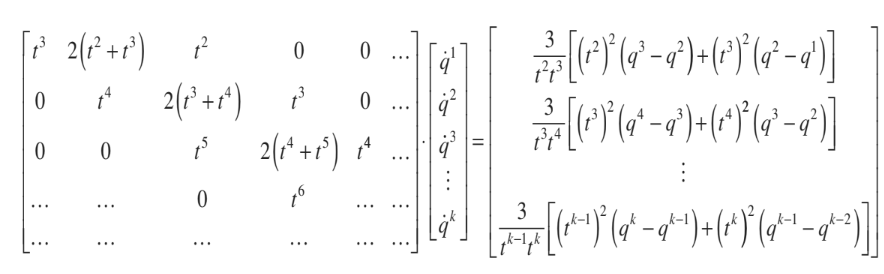

I'm not typing that...